# Test 1

## Problema 1

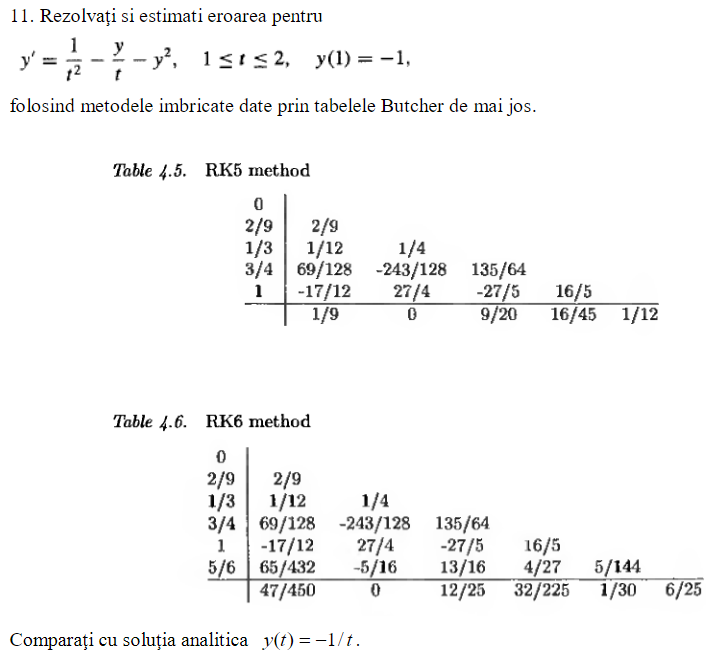

### Metoda RK5

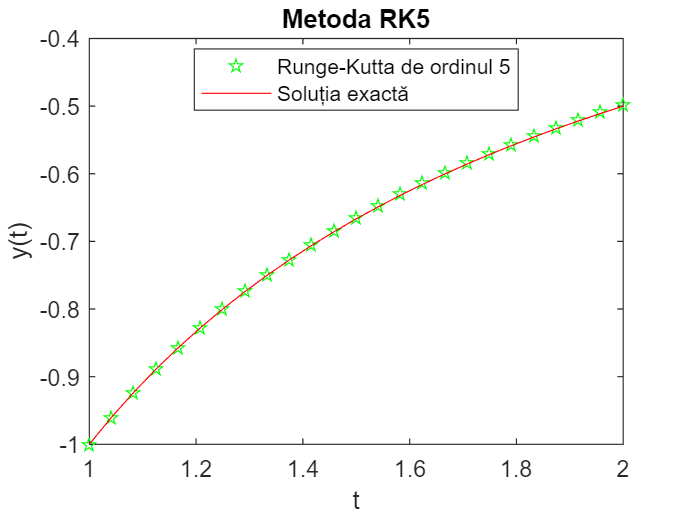

a = 1; b = 2; %capetele intervalului
N = 25; %pasul rețelei
h = (b - a) / (N - 1); %numărul de noduri
y = zeros(N, 1);%inițializăm vectorul soluție
ye = zeros(N, 1); %soluția exactă
y(1)=-1; ye(1)=-1; %condițiile inițiale
t = a:h:b; %pașii de timp
for i = 2 : N
    K1 = fEx(t(i - 1), y(i-1));
    K2 = fEx(t(i - 1) + 2 * h / 9, y(i - 1) + 2 * h * K1 / 9);
    K3 = fEx(t(i - 1) + h / 3, y(i - 1) + K1 * h / 12 + h * K2 / 4);
    K4 = fEx(t(i - 1) + 3 * h / 4, y(i - 1) + K1 * h * 69 / 128 + K2 * h * (-243) / 128 + h * K3 * 125 / 64);
    K5 = fEx(t(i - 1) + h, y(i - 1) + K1 * h * (-17) / 12 + K2 * h * 27 / 4 + K3 * h * (-27) / 5 + K4 * h * 16/5);
    y(i) = y(i - 1) + h * (K1 / 9 + 9 * K3 / 20 + 16 * K4 / 45 + K5 / 12);
    ye(i) = -1 / t(i);
end
plot(t, y, 'gp')
hold on
plot(t, ye, 'r')
title('Metoda RK5')
legend('Runge-Kutta de ordinul 5', 'Soluția exactă', Location='best')
xlabel('t')
ylabel('y(t)')
hold off

fprintf('Eroarea este %.16e.', norm(ye-y,Inf))

Eroarea este 2.4415580702475959e-03.

### Metoda RK6

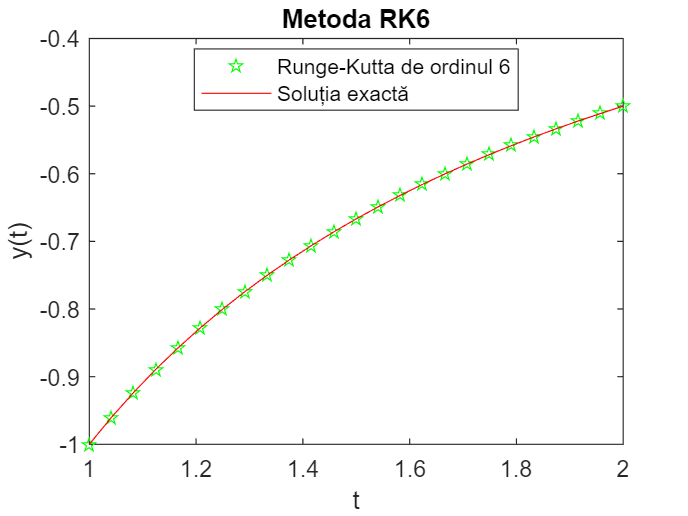

for i = 2 : N
    K1 = fEx(t(i - 1), y(i-1));
    K2 = fEx(t(i - 1) + 2 * h / 9, y(i - 1) + 2 * h * K1 / 9);
    K3 = fEx(t(i - 1) + h / 3, y(i - 1) + K1 * h / 12 + h * K2 / 4);
    K4 = fEx(t(i - 1) + 3 * h / 4, y(i - 1) + K1 * h * 69 / 128 + K2 * h * (-243) / 128 + h * K3 * 125 / 64);
    K5 = fEx(t(i - 1) + h, y(i - 1) + K1 * h * (-17) / 12 + K2 * h * 27 / 4 + K3 * h * (-27) / 5 + K5 * h * 16/5);
    K6 = fEx(t(i - 1) + 5 * h / 6, y(i - 1) + K1 * h * 65 / 432 + K2 * h * (-5) / 16 + K3 * h * 13 / 16 + K4 * h * 4 / 27 + K5 * h * 5 / 144);
    y(i) = y(i - 1) + h * (47 * K1 / 450 + 12 * K3 / 25 + 32 * K4 / 225 + K5 / 30 + 6 * K6 / 25);
    ye(i) = -1 / t(i);
end
plot(a : h : b, y, 'gp')
hold on
plot(a : h : b, ye, 'r')
title('Metoda RK6')
legend('Runge-Kutta de ordinul 6', 'Soluția exactă', Location='best')
xlabel('t')
ylabel('y(t)')
hold off

fprintf('Eroarea este %.16e.', norm(ye-y,Inf))

Eroarea este 9.9658136662961194e-04.

## Problema 2

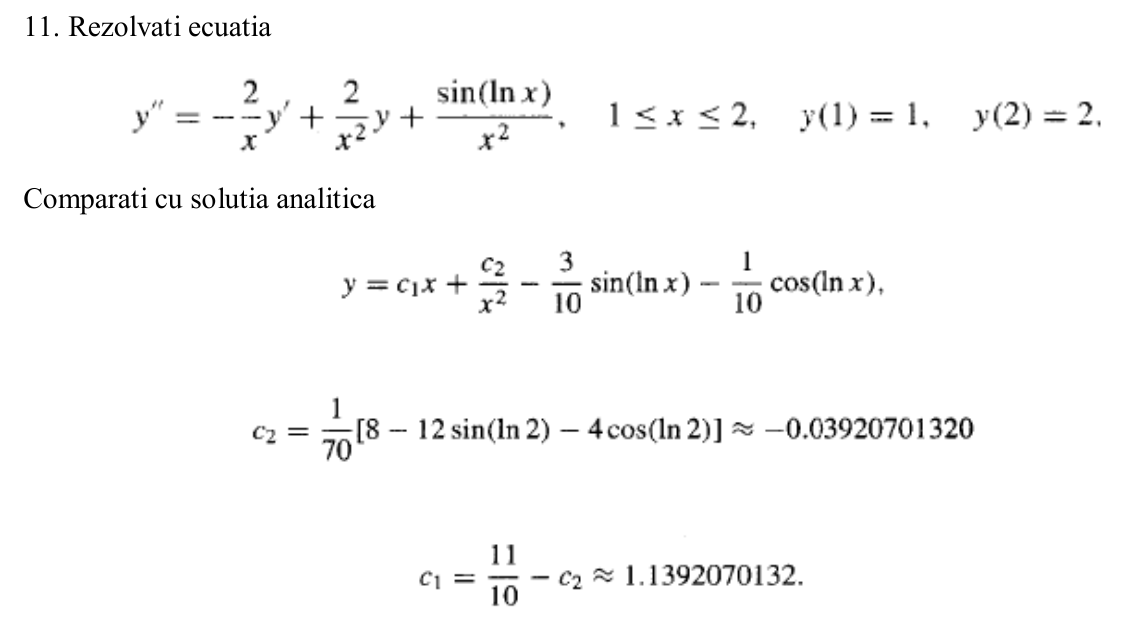

opts = bvpset('FJacobian',@jac,'RelTol',0.1,'AbsTol',0.1,'Stats','on');
xmesh = linspace(1, 2, 25);
solinit = bvpinit(xmesh, [1; 2]);
sol4c = bvp4c(@bvpfcn, @bcfcn, solinit, opts);

The solution was obtained on a mesh of 25 points.
The maximum residual is  2.001e-06. 
There were 147 calls to the ODE function. 
There were 10 calls to the BC function. 


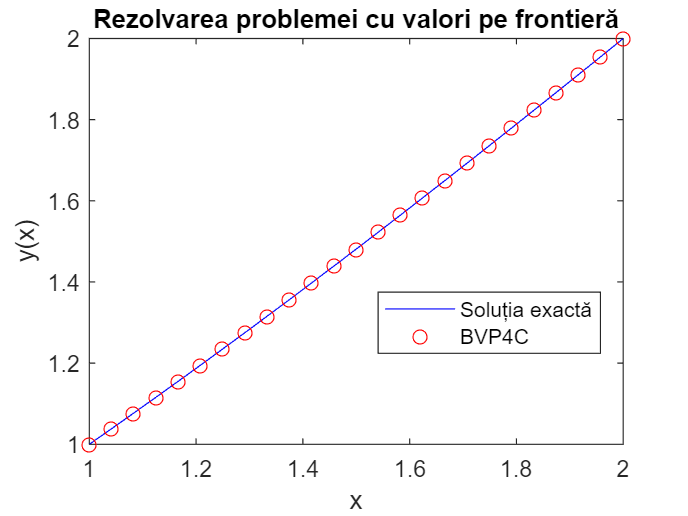

xplot = linspace(1,2,25);
c2 = 1/70*(8 - 12*sin(log(2)) - 4*cos(log(2)));
c1 = 11/10 - c2;
yplot = c1*xplot + c2./xplot.^2 - 3/10*sin(log(xplot)) - 1/10*cos(log(xplot));
plot(xplot,yplot(1,:),'b',sol4c.x,sol4c.y(1,:),'ro')
title('Rezolvarea problemei cu valori pe frontieră')
legend('Soluția exactă','BVP4C', Location='best')
xlabel('x')
ylabel('y(x)')

fprintf('Eroarea este %.16e.', norm(sol4c.y(1,:) - yplot,Inf))

Eroarea este 6.8858752033662540e-09.

## Funcții auxiliare

function rez = fEx(t, y)
    rez = 1 / (t ^ 2) - y /t - y ^ 2;
end

function dydx = bvpfcn(x,y)
    dydx = [y(2)
            -2*y(2)/x + 2*y(1)/x^2 + sin(log(x))/x^2];
end

function res = bcfcn(ya,yb)
res = [ya(1)-1
       yb(1)-2];
end

function dfdy = jac(x,y)
dfdy = [0      1
       2/x^2 -2/x];
end